clc
clear
x=[4,8,4,6,8,6,7,7,7,8,10,9,7,6,10,8,5,9,6,3,7,6,4,7,6,9,7,4,7,6,8,8,9,11,8,7,10,8,5,7,7,6,5,10,8,9,7,5,6,6,8,8,9,11,8,7,10,8];
n=length(x)

n = 58

min(x)

ans = 3

max(x)

ans = 11

r=range(x)

r = 8

 
K=5

K = 5

l=r/K

l = 1.6000

L=ceil(l)

L = 2


m1=4;
m=[m1 m1+L m1+(2*L) m1+(3*L) m1+(4*L)]

m =      4     6     8    10    12


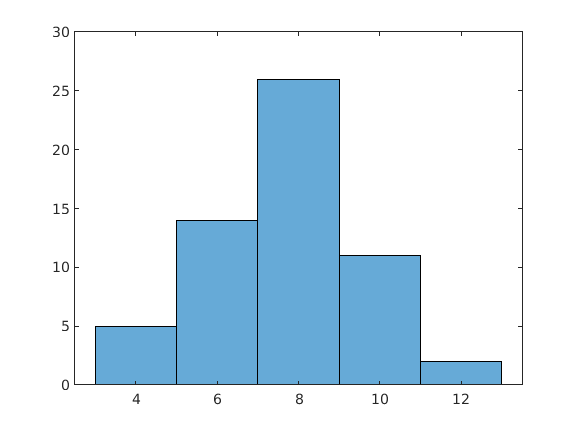

h =   Histogram with properties:

             Data: [4 8 4 6 8 6 7 7 7 8 10 9 7 6 10 8 5 9 6 3 7 6 4 7 6 9 7 4 7 6 8 8 9 11 8 7 10 8 5 7 7 6 5 10 8 9 7 5 6 6 8 8 9 11 8 7 10 8]
           Values: [5 14 26 11 2]
          NumBins: 5
         BinEdges: [3 5 7 9 11 13]
         BinWidth: 2
        BinLimits: [3 13]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


marca=m';

intervalo=[3:2:13];
h=histogram(x,intervalo)

frecuencia=h.Values;

fa=frecuencia';
fr=fa/n;
F=cumsum(fa);
Fr=F/n;
table(marca,fa,fr,F,Fr)

ans = 5×5 table
    marca    fa       fr       F        Fr   
    _____    __    ________    __    ________

      4       5    0.086207     5    0.086207
      6      14     0.24138    19     0.32759
      8      26     0.44828    45     0.77586
     10      11     0.18966    56     0.96552
     12       2    0.034483    58           1


%histograma
intervalo=[3:2:13]

intervalo =      3     5     7     9    11    13


h=histogram(x,intervalo)

h =   Histogram with properties:

             Data: [4 8 4 6 8 6 7 7 7 8 10 9 7 6 10 8 5 9 6 3 7 6 4 7 6 9 7 4 7 6 8 8 9 11 8 7 10 8 5 7 7 6 5 10 8 9 7 5 6 6 8 8 9 11 8 7 10 8]
           Values: [5 14 26 11 2]
          NumBins: 5
         BinEdges: [3 5 7 9 11 13]
         BinWidth: 2
        BinLimits: [3 13]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


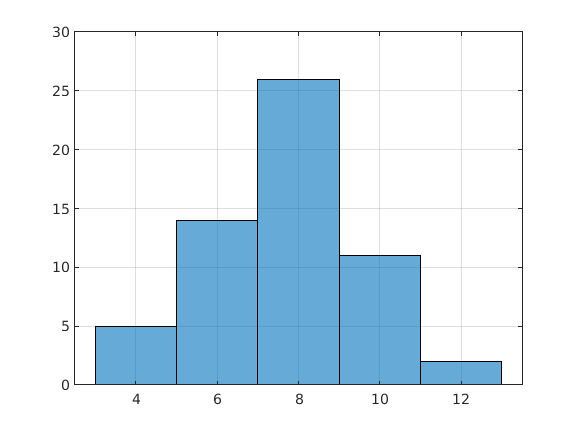

grid on

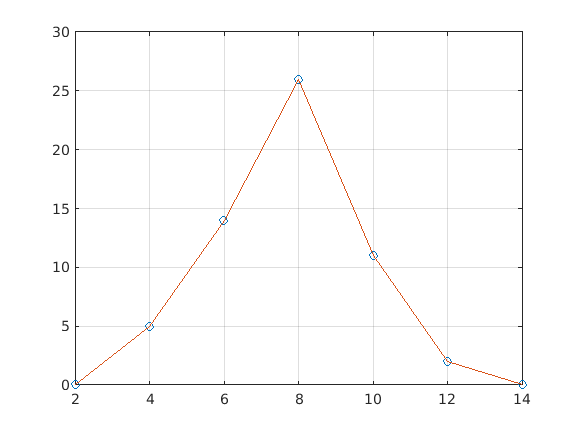


%poligono
frecuencia=h.Values;
mp=[2 m 14];
fp=[0 frecuencia 0];
figure
plot(mp,fp,'o',mp,fp)
grid on

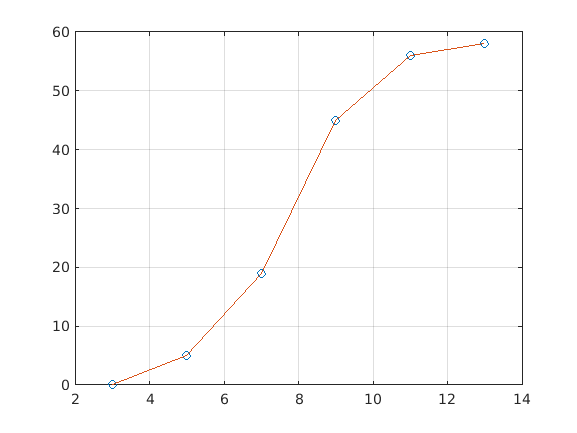


%ojiva
frecuencia_acum=cumsum(frecuencia);
FR=[0 frecuencia_acum];
figure
plot(intervalo,FR,'o',intervalo,FR)
grid on

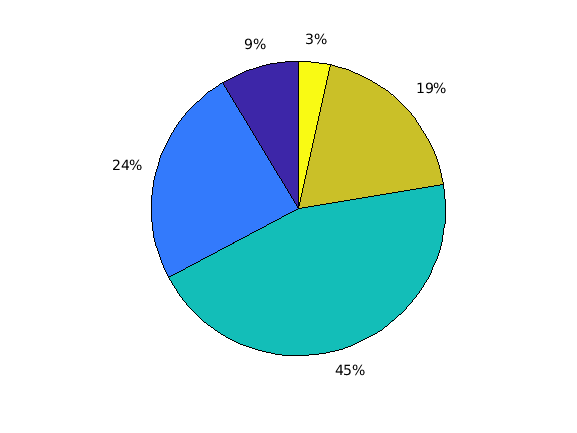



%tortas
figure
pie(frecuencia)